SS=MS(:,1); %SeaState
WD=MS(:,2).*100+MS(:,3).*10+MS(:,4).*1;%WaveDirection
SD=MS(:,5).*100+MS(:,6).*10+MS(:,7).*1;%SwellDirection
MH=MS(:,8).*10+ MS(:,9).*1+ MS(:,10).*0.1;%MaxWaveHeight
OH=MS(:,11).*10+MS(:,12).*1+MS(:,13).*0.1;%OneTenthMaxWaveHeight
Pd=MS(:,14).*10+MS(:,15).*1+MS(:,16).*0.1;%Period
WD(WD>996) = [];
SD(SD>996) = [];
MH(MH>99.6) = [];
OH(OH>99.6) = [];
Pd(Pd>99.6) = [];
WD=WD.*3.1416/180;
SD=SD.*3.1416/180;

% WD=roundn(WD,-1);
% SD=roundn(SD,-1);
% MH=roundn(MH,-1);
% OH=roundn(OH,-1);
% Pd=roundn(Pd,-1);

SS1 = tabulate(SS);%统计数组（x）中元素出现的频率
SS2 = array2table(SS1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
Pd1 = tabulate(Pd);%统计数组（x）中元素出现的频率
Pd2 = array2table(Pd1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
MH1 = tabulate(MH);%统计数组（x）中元素出现的频率
MH2 = array2table(MH1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
WD1 = tabulate(WD);%统计数组（x）中元素出现的频率
WD2 = array2table(WD1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
SD1 = tabulate(SD);%统计数组（x）中元素出现的频率
SD2 = array2table(SD1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
OH1 = tabulate(OH);%统计数组（x）中元素出现的频率
OH2 = array2table(OH1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表

figure()
% subplot(231)
% bar(SS2.Value,SS2.Count);
% xlabel("grade");
% ylabel("Count")
% title("SeaState")
% 
% subplot(232)
% bar(Pd2.Value,Pd2.Count);
% xlabel("s");
% ylabel("Count")
% title("Period")

% subplot(233)
subplot (121)
bar(MH2.Value,MH2.Count);
xlabel("Value (m)");
ylabel("Count")
title("Max Wave Height")

% subplot(234)
% bar(OH2.Value,OH2.Count);
% xlabel("m");
% ylabel("Count")
% title("OneTenthMaxWaveHeight")
% 
% subplot(235)
% bar(WD2.Value,WD2.Count);
% xlabel("rad");
% ylabel("Count")
% title("WaveDirection")
% 
% subplot(236)
% bar(SD2.Value,SD2.Count);
% xlabel("rad");
% ylabel("Count")
% title("SwellDirection")

% figure()
subplot(122)
[f,xi]=ksdensity(MH);
plot(xi,f,'r*');
hold on
[miu,sigma]= normfit(MH,0.05)

miu = 1.0003

sigma = 0.4429

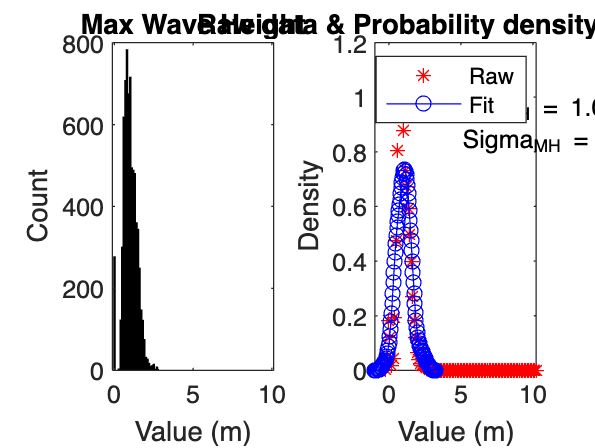

% [mu,sigma,muci,sigmaci]= normfit(data,a);
% data: 原数据
% a :置信度
% mu: 均值
% sigma: 标准差
% muci:1-a 区间内的均值
% sigmaci:1-a 区间内的标准差
TJ=ones(100,1);
LTJ=length(TJ);
zt0=normrnd(miu,sigma,1,LTJ);
[f1,xi1]=ksdensity(zt0);
plot(xi1,f1,'b-o');
hold off
xlabel('Value (m)')
ylabel('Density')
legend('Raw','Fit')
title("Raw data & Probability density function")
txt = { ['Miu_{MH} = ' num2str(miu)]; ['Sigma_{MH} = ' num2str(sigma)] };
text(xi(50),f(50)+0.9,txt)